**Implement alternative PVT computation block to target one (or more) moon more realistic navigation scenarios. Examples:**

   1) The receiver is equipped with an altimeter.

         [altimeter] = We have input data t fixed values with Gaussian

         noise.

   2) The receiver is a rover exploring the Moon, equipped with an inertial measurement unit (IMU).

   (Kalman Filter). 

          **  [accelerometer]** = calculate distance, we need double integration of acceleration,

            but we will have noise

          **  [magnetometer] **= to identify the north direction 

          **  [gyroscope]** = to identify change in orientation or rotation

          **  [Kalman] **= to estimate receiver position, smoothing the  tracking (or estimate when there is temporary GNSS

            unavailability

   3) There is a Moon station transmitting a ranging signal to the receiver/rover (Differential

       positioning).

        **[Reference Station] **= we have station with fixed position. It

        calculates pseudoranges from satellites and send to the

        receiver/rover. Least square function is recommended. 

   **To be described in the report**

       Discuss the performances of the developed PVT techniques, comparing the measured with the true

       data, estimating:

       **1) solution accuracy** @ Kaplan 11.2.3 

           -- Standards based on a measurement interval of 24 hours averaged over all

               points in the service volume;

           • Global average position domain accuracy: <= 9m 95% horizontal error

               and <= 15m 95% vertical error;

           • Worst site position domain accuracy: <= 17m 95% horizontal error and

               <= 37m 95% vertical error;

           • Time transfer domain accuracy: <= 40 ns time transfer error 95% of time (SIS only).

      ** 2) availability,**    (@ Kaplan Chapter 11.3) = Here we show number

       of satellite per t time. 

       **3) dilution of precision (DOP)**  @.Kaplan 11.2.1 = We can visualize

       it as given in my Github readme page. 

 *  Also we can improve our code if we detect anomalies: *

*  - e.g. 92% cases are clock jumps and other clock anomalies. We can plot the result *

close all ;
clear all;
clc;

settings = initSettings();
addpath include            
addpath geoFunctions 
addpath data/imu

## Initialize data

gnssdata = rinexread("BRDC00WRD_R_20221260000_01D_EN.rnx").Galileo;

## We get unique satellites (however, in the final version we include all dublicates as well)

[~,satIdx] = unique(gnssdata.SatelliteID); 
gnssdata = gnssdata(satIdx,:);

## Ephemeris preparation

for d=1
eph.t_oc      	=	gnssdata.TransmissionTime;%Transmission time of the message
eph.a_f2	=	gnssdata.SVClockDriftRate;%SV clock drift rate in seconds per second squared
eph.a_f1 	=	gnssdata.SVClockDrift;%SV clock drift in seconds per second
eph.a_f0 	=	gnssdata.SVClockBias;%SV clock bias in seconds
eph.T_GD 	=	gnssdata.BRDCOrbit5Spare4;%THis value exists in GPS and GLONASS, but in Galileo we can put some constant or exclude it
eph.sqrtA 	=	gnssdata.sqrtA;%Square root of the semimajor axis (sqrt(m))
eph.t_oe 	=	gnssdata.Toe;%	Time of ephemeris (seconds of respective satellite week)
eph.deltan 	=	gnssdata.Delta_n;%Mean motion difference from the computed value at reference time, in radians per second.
eph.M_0 	=	gnssdata.M0;%	Mean anomaly at the reference time, in radians
eph.e	=	gnssdata.Eccentricity;% Eccentricity
eph.omega  	=	gnssdata.omega;% Argument of perigee, in radians
eph.C_uc	=	gnssdata.Cuc;% Amplitude of the cosine harmonic correction term to the argument of latitude, in radians
eph.C_us 	=	gnssdata.Cus;% 	Amplitude of the sine harmonic correction term to the argument of latitude, in radians
eph.C_rc	=	gnssdata.Crc;% 	Amplitude of the cosine harmonic correction term to the orbit radius, in meters
eph.C_rs	=	gnssdata.Crs;%  Amplitude of the sine harmonic correction term to the orbit radius, in meters
eph.i_0	=	gnssdata.i0;% Inclination angle at reference time, in radians
eph.C_ic	=	gnssdata.Cic;% 	Amplitude of the cosine harmonic correction term to the angle of inclination, in radians
eph.C_is	=	gnssdata.Cis;% Amplitude of the sine harmonic correction term to the angle of inclination, in radians
eph.omega_0	=	gnssdata.OMEGA0;% 	Longitude of ascending node of orbit plane at weekly epoch, in radians.
eph.omegaDot	=	gnssdata.OMEGA_DOT;% Reference rate of right ascension, in radians per second
eph.iDot = gnssdata.IDOT;%Rate of inclination angle, in radians per second
eph.transmitTime = gnssdata.GALWeek;% GAL week number, with Toe. Continuous number, not mod(1024).
end

## Observation data preparation

obs.Time               =0        %SBAS clock time

obs = struct with fields:
    Time: 0


obs.SatelliteID        =0;       %Satellite system (S) number
obs.SVClockBias        =0;       %SV clock bias in seconds
obs.SVFrequencyBias    =0;       %SV relative frequency bias in hertz
obs.TransmissionTime   =0;       %Transmission time of the message
obs.PositionX          =0;       %Satellite position X in kilometers
obs.VelocityX          =0;       %Satellite velocity X dot in kilometers per second
obs.AccelerationX      =0;       %Satellite acceleration X in kilometers per second squared
obs.Health             =0;       %Health: SBAS: See RINEX 3.05 Standard section 5.4.4 for: health
obs.PositionY          =0;       %Satellite position Y in kilometers
obs.VelocityY          =0;       %Satellite velocity Y dot in kilometers per second
obs.AccelerationY      =0;       %Satellite acceleration Y in kilometers per second squared
obs.AccuracyCode       =0;       %Accuracy code (URA
obs.PositionZ          =0;       %Satellite position Z in kilometers
obs.VelocityZ          =0;       %Satellite velocity Z dot in kilometers per second
obs.AccelerationZ      =0;       %Satellite acceleration Z in kilometers per second squared
obs.IODN               =0;       %Issue number of the satellite navigation data set

## Until now we do not have pseudorange and pseudorange rate. Therefore, we have dummy input data.

prnList = zeros(height(gnssdata),1);
prnList(:) = 24701805;
for i = 1:height(gnssdata)
prnList(i) = prnList(i) + rand(1,1)*5002709;
end
satVel = zeros(height(gnssdata),3);
satVel(:,:) = -3500;
prnRate = zeros(height(gnssdata),1);
prnRate(:,:) = -500+rand(1,1)*1000;
for i = 1:height(gnssdata)
satVel(i,1) = satVel(i,1) + rand(1,1)*7000;
satVel(i,2) = satVel(i,2) + rand(1,1)*7000;
satVel(i,3) = satVel(i,3) + rand(1,1)*7000;
end

%ls w/o alyitude    

## Satellite position and satellite clock correction

[satPositions, satClkCorr] = satposition(eph.transmitTime, prnList, eph, settings);


satpos = satPositions;
satpos1 = satPositions.';
obs = prnRate;
%[pos, el, az,dop] = leastSquarePosition(satPositions, prnRate, settings);
for d=1
nmbOfIterations = 7;

dtr     = pi/180;
pos     = zeros(4, 1);
X       = satpos;
nmbOfSatellites = size(satpos, 2);

A       = zeros(nmbOfSatellites, 4);
omc     = zeros(nmbOfSatellites, 1);
az      = zeros(1, nmbOfSatellites);
el      = az;

%=== Iteratively find receiver position ===================================
for iter = 1:nmbOfIterations

    for i = 1:nmbOfSatellites
        if iter == 1
            %--- Initialize variables at the first iteration --------------
            Rot_X = X(:, i);
            trop = 2;
        else
            %--- Update equations -----------------------------------------
            rho2 = (X(1, i) - pos(1))^2 + (X(2, i) - pos(2))^2 + ...
                   (X(3, i) - pos(3))^2;
            traveltime = sqrt(rho2) / settings.c ;

            %--- Correct satellite position (do to earth rotation) --------
            Rot_X = e_r_corr(traveltime, X(:, i));

            %--- Find the elevation angel of the satellite ----------------
            [az(i), el(i), dist] = topocent(pos(1:3, :), Rot_X - pos(1:3, :));

            if (settings.useTropCorr == 1)
                %--- Calculate tropospheric correction --------------------
                trop = tropo(sin(el(i) * dtr), ...
                             0.0, 1013.0, 293.0, 50.0, 0.0, 0.0, 0.0);
            else
                % Do not calculate or apply the tropospheric corrections
                trop = 0;
            end
        end % if iter == 1 ... ... else 

        %--- Apply the corrections ----------------------------------------
        omc(i) = (obs(i) - norm(Rot_X - pos(1:3), 'fro') );

        %--- Construct the A matrix ---------------------------------------
        A(i, :) =  [ (-(Rot_X(1) - pos(1))) / obs(i); ...
                     (-(Rot_X(2) - pos(2))) / obs(i); ...
                     (-(Rot_X(3) - pos(3))) / obs(i);
                     1];
    end % for i = 1:nmbOfSatellites

    % These lines allow the code to exit gracefully in case of any errors


    %--- Find position update ---------------------------------------------
    x   = A \ omc;
    
    %--- Apply position update --------------------------------------------
    pos = pos + x;
    
end % for iter = 1:nmbOfIterations

pos = pos';

%=== Calculate Dilution Of Precision ======================================

    %--- Initialize output ------------------------------------------------
    dop     = zeros(1, 5);
    
    %--- Calculate DOP ----------------------------------------------------
    Q       = inv(A'*A);
    
    dop(1)  = sqrt(trace(Q));                       % GDOP    
    dop(2)  = sqrt(Q(1,1) + Q(2,2) + Q(3,3));       % PDOP
    dop(3)  = sqrt(Q(1,1) + Q(2,2));                % HDOP
    dop(4)  = sqrt(Q(3,3));                         % VDOP
   dop(5)  = sqrt(Q(4,4));                         % TDOP

end
%initPosECEF = [satPositions(:,1) satPositions(:,2) satPositions(:,3)]; There should be the location of the first satellite
% position. 
%initVelECEF = [0 0 0]; We can keep thius value
[lla1, gnssVel1, hdop1, vdop1] = receiverposition(prnList,satpos1,prnRate,satVel);
%geoplot(lla1(1),lla1(2));
%geobasemap topographic
%skyplot(az,abs(el),satIdx); 
poss = pos;

LLA = xyz2lla(poss(1:3));

## This is the end of the code. Below some functions which might be used in the future

p = prnList;
pdot = prnRate;


%satpos = satpos.';

validateattributes(p, {'double', 'single'}, {'vector', 'real', 'finite'});

N = numel(p);
%validateattributes(satpos, {'double', 'single'}, {'2d', 'nrows', N, 'ncols', 3, 'real', 'finite'});

validateattributes(pdot, {'double', 'single'}, ...
    {'vector', 'numel', N, 'real', 'finite'});

validateattributes(satVel, {'double', 'single'}, ...
    {'2d', 'nrows', N, 'ncols', 3, 'real', 'finite'});

refFrame = fusion.internal.frames.NED;

initPosECEF = [satpos(:,1)];
initVelECEF = [0 0 0];
[posECEF, gnssVelECEF, dopMatrix] = computeLocation(p, pdot, satpos1, satVel, initPosECEF, initVelECEF);
%[Az, El, D] = topocent(X, dx);
lla = ecef2lla(posECEF);
T = eye(4, 'like', dopMatrix);
%{
T(1:3,1:3) = refFrame.ecef2framerotmat(lla(1), lla(2));

% Convert from ECEF to local frame.
dopMatrix = T * dopMatrix * T.';

diagDOPMat = diag(dopMatrix);
gdop
tdop
hdop = sqrt(sum(diagDOPMat(1:2)));
vdop = sqrt(diagDOPMat(3));
%}

## Calculate displacement according to accelerometer

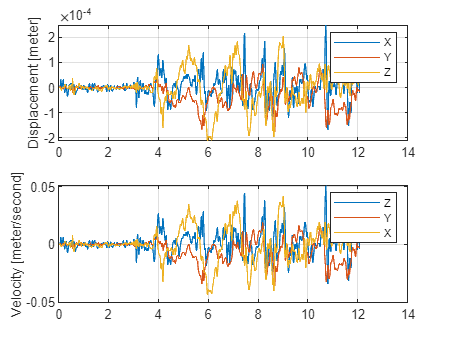

acc_raw = readmatrix("Accelerometer.csv");
acc_raw1 = readmatrix("acc.csv");

initialECEF = zeros(length(acc_raw1),4);
initialVel = zeros(length(acc_raw1),4);

 k=1237;
acc_raw (:,1:2) = [];

velocity = zeros(length(acc_raw1), 4);

displacement = zeros(length(acc_raw1), 4);

% calculating velocity v = a*t .
for i = 2:length(acc_raw1)
    t = acc_raw1(i,1) -acc_raw1(i-1,1);
    velocity(i,:) = [acc_raw1(i,1),acc_raw1(i,2)*t,acc_raw1(i,3)*t,acc_raw1(i,4)*t];
end 

% calculating displacement S = (a*t^2)/2 .
for i = 2:length(acc_raw1)
    t = acc_raw1(i,1) -acc_raw1(i-1,1);
    displacement(i,:) = [acc_raw1(i,1),acc_raw1(i,2)*(t^2)/2,acc_raw1(i,3)*(t^2)/2,acc_raw1(i,4)*(t^2)/2];
end 
initialVel = initialVel   + velocity; 
initialECEF = initialECEF + displacement;

figure("Name","Accelerometer (displacement and velocity)")

subplot(2,1,1)
plot(initialECEF(:,1), initialECEF(:,2));
hold on 
plot(initialECEF(:,1), initialECEF(:,3));

 hold on
plot(initialECEF(:,1), initialECEF(:,4));
grid  on
ylabel("Displacement [meter]");
legend("X","Y","Z");

subplot(2,1,2)
plot(initialVel(:,1), initialVel(:,2));
hold on
plot(initialVel(:,1), initialVel(:,3));
hold on
plot(initialVel(:,1), initialVel(:,4));
hold off
grid on
ylabel("Velocity [meter/second]");
legend("Z","Y","X");  %!!! Correct your input, because there are z,y,x, NOT x,y,z

## Differential Positioning - Lunar reference station 

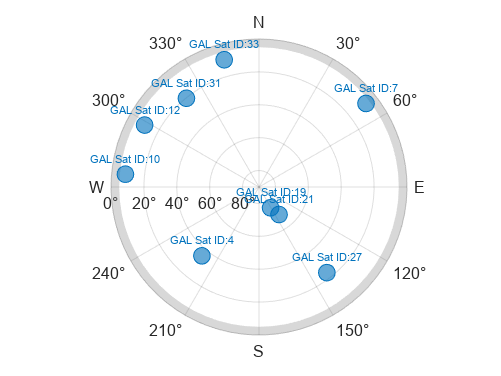

  recPos = [0 0 0];
recVel = [0 0 0];

% Specify simulation times.
startTime = datetime(2023,5,22,8,0,0,"TimeZone","America/New_York");
simulationSteps = size(pos,1);
dt = 1;
stopTime = startTime + seconds((simulationSteps-1)*dt);

% Specify mask angle.
maskAngle = 5; % degrees

% Convert receiver position from north-east-down (NED) to geodetic
% coordinates.
receiverLLA = ned2lla(recPos,lla1,"ellipsoid");

% Specify the RINEX file.
%rinexFile = "GODS00USA_R_20211750000_01D_GN.rnx";
rinexFile = "BRDC00WRD_R_20221260000_01D_EN.rnx";

% Set RNG seed to allow for repeatable results. 
rng("default");

% Create scenario.
sc = satelliteScenario(startTime, stopTime, dt);

% Initialize satellites. 
navmsg = rinexread(rinexFile);
satellite(sc,navmsg);
satID = sc.Satellites.Name;

% Preallocate results.
numSats = numel(sc.Satellites);
allSatPos = zeros(numSats,3,simulationSteps);
allSatVel = zeros(numSats,3,simulationSteps);

% Save satellite states over entire simulation.
for i = 1:numel(sc.Satellites)
    [oneSatPos, oneSatVel] = states(sc.Satellites(i),"CoordinateFrame","ecef");
    allSatPos(i,:,:) = permute(oneSatPos,[3 1 2]);
    allSatVel(i,:,:) = permute(oneSatVel,[3 1 2]);
end

% Preallocate results.
allP = zeros(numSats,simulationSteps);
allPDot = zeros(numSats,simulationSteps);
allIsSatVisible = false(numSats,simulationSteps);

% Use the skyplot to visualize satellites in view.
figure
sp = skyplot([],[],MaskElevation=maskAngle);

for idx = 1:simulationSteps
    satPos = allSatPos(:,:,idx);
    satVel = allSatVel(:,:,idx);
    
    % Calculate satellite visibilities from receiver position.
    [satAz,satEl,allIsSatVisible(:,idx)] = lookangles(receiverLLA(idx,:),satPos,maskAngle);
    
    % Calculate pseudoranges and pseudorange rates using satellite and
    % receiver positions and velocities.
    [allP(:,idx),allPDot(:,idx)] = pseudoranges(receiverLLA(idx,:),satPos,recVel(idx,:),satVel);
    
    set(sp,"AzimuthData",satAz(allIsSatVisible(:,idx)), ...
        "ElevationData",satEl(allIsSatVisible(:,idx)), ...
        "LabelData",satID(allIsSatVisible(:,idx)))
    drawnow limitrate
end


% Preallocate results.
lla = zeros(simulationSteps,3);
gnssVel = zeros(simulationSteps,3);
hdop = zeros(simulationSteps,1);
vdop = zeros(simulationSteps,1);

for idx = 1:simulationSteps
    p = allP(:,idx);
    pdot = allPDot(:,idx);
    isSatVisible = allIsSatVisible(:,idx);
    satPos = allSatPos(:,:,idx);
    satVel = allSatVel(:,:,idx);
    
    % Estimate receiver position and velocity using pseudoranges,
    % pseudorange rates, and satellite positions and velocities.
    [lla(idx,:),gnssVel(idx,:),hdop(idx,:),vdop(idx,:)] = receiverposition(p(isSatVisible),...
        satPos(isSatVisible,:),pdot(isSatVisible),satVel(isSatVisible,:));
end



## Calculate

## Plotting spherical shape with Lunar image. Then, show gnss point on the sphere (it is optional)

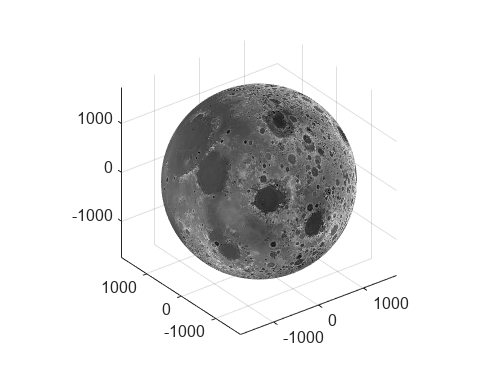

    c=imread("Lunar_map.jpg");
    center = [0 0 0]; % center of the sphere
  radius = 1737;
    % Initalize longitude and colatitude range
    longitude = deg2rad(linspace(0,360,size(c,2)));
    colatitude = deg2rad(linspace(90,-90,size(c,1)));
    
    circle_center = [0.5 0.5 0.5]; % center of the circle
circle_radius = 0.3; % radius of the circle
theta_circle = linspace(0, 2*pi, 100); % azimuthal angle for the circle
phi_circle = linspace(0, pi, 50); % polar angle for the circle
[theta_circle, phi_circle] = meshgrid(theta_circle, phi_circle);

x_circle = circle_center(1) + circle_radius*sin(phi_circle).*cos(theta_circle);
y_circle = circle_center(2) + circle_radius*sin(phi_circle).*sin(theta_circle);
z_circle = circle_center(3) + circle_radius*cos(phi_circle);


    % Initialize empty variables
    X = zeros(size(c,1),size(c,2));
    Y = zeros(size(c,1),size(c,2));
    Z = zeros(size(c,1),size(c,2));
    % Convert spherical to cartesian coordinates
    for j = 1:length(colatitude)
        for i = 1:length(longitude)
            [X(j,i), Y(j,i), Z(j,i)] = sph2cart( ...
                                            longitude(i),...
                                            colatitude(j),...
                                            radius);
        end
    end
n=30;
r = 10; % radius of the sphere

thetha = 0:pi/(n/2):2*pi; 
phi    = -pi:2*pi/n:pi;
xp     = r.*sin(phi).*cos(thetha);
yp     = r.*sin(thetha).*sin(phi);
zp     = r.*cos(phi);

    figure
    %scatter3(X(100),Y(100),Z(100));
   % hold on
        surf(X,Y,Z,c,'EdgeColor','none','FaceColor','texturemap');
    axis equal
    hold off

## This is test, n (time) and HDOP, VDOP, TDOP values are place in the final version

    n = zeros(k,1);
    vdop11 = zeros(k,1);
        hdop11 = zeros(k,1);
        for i= 1:k
        n(i) = i;
    end

## Solution accuracy

%  Calculate of HDOP and VDOP
%  Set Threshold 9 meter for HDOP with 95% and 17 meter for VDOP with 95%
%   Set Threshold 17 meter for HDOP with 95% and 37 meter for VDOP with 95%
% Set Threshold 40ns for TDOP with 95% accuracy 
%

## Plotting Availability

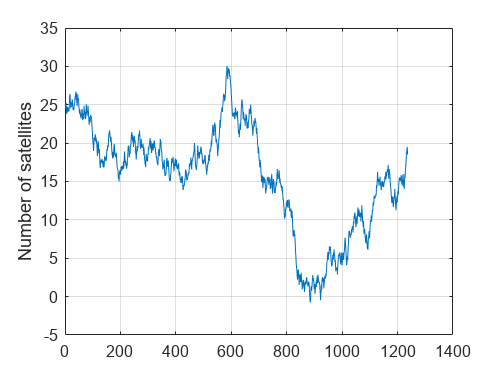

    satIdxx = zeros(k,1);

for i= 1:k
        if i==1
          satIdxx(i) = length(satIdx);
        else
        satIdxx(i) = satIdxx(i-1) + (2*rand(1,1)-0.99);
        end
end


figure("Name","Availability");
plot(n,satIdxx);
ylabel("Number of satellites");

grid on

## Plotting Delusion of Precision

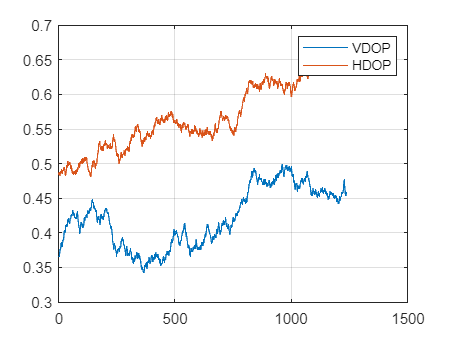

   for i= 1:k
        if i==1
          vdop11(i) = vdop1;
        else
        vdop11(i) = vdop11(i-1) + (-0.5+rand(1,1)) *0.01;
        end
    end

        for i= 1:k
        if i==1
          hdop11(i) = hdop1;
        else
        hdop11(i) = hdop11(i-1) + (-0.5+rand(1,1)) *0.01;
        end
        
        end

   
figure ("Name","Dilusion of Precision")
plot(n,vdop11);
hold on
plot(n,hdop11);
legend('VDOP','HDOP');
hold off
grid on

  
  disp("Successfully compiled!!!")

Successfully compiled!!!
